# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_dgm.mlx
    ---------------
    This code solves the deterministic growth model using value function iteration.

%}

## Model: Deterministic Growth Model.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \sum_{t=1}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = k_t^{\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t + i_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \text{ ,}$$


where the constraints hold for for $t = 1, 2, ...,$ . The first constraint is the aggregate resource constraint; the second is production; the third is the law of motion for capital. Consumption is restricted to be positive, meaning people should not starve. Capital is restricted to be positive so goods can be produced for consumption.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$V_t(k_t) = \underset{c_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(k_{t+1}) \ ,$$


 
$$\begin{array}{r l} \text{s.t. }  k_t^{\alpha} = c_t + k_{t+1} - (1-\delta)k_t \end{array} \ \text{for} \ t = 1, 2, ... \text{ ,}$$



$$c_t > 0,  k_t > 0 \text{ .}$$


The state space consists only of $k_t$ while the choice space consists of $c_t$ and $k_{t+1}$. Substituting the combined constraint into the utility function gives


$$V_t(k_t) = \underset{k_{t+1}}{\text{max}}\frac{\left(k_t^{\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(k_{t+1}) \ ,$$



$$k_t  > 0 \text{ ,}$$


which reduces the choice space to $k_{t+1}$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:/Users/',id,'/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/vfi_dgm_matlab/'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:/Users/xmgb/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/vfi_dgm_matlab/ 



## Set the parameters and generate the state space.

Calls: model.m.

From (5.3) in Adda and Cooper, the Euler Equation is


$$c_t^{-\sigma} = \beta c_{t+1}^{-\sigma} (\alpha k_{t+1}^{\alpha-1}+(1-\delta)) \ .$$


In the steady state, $c_t=c_{t+1}=c^{ss}$ so


$$1 = \beta (\alpha k_{t+1}^{\alpha-1}+(1-\delta)) \ , \\
\frac{1}{\beta} = \alpha k_{t+1}^{\alpha-1}+(1-\delta) \ , \\
k^{ss} = \left(\frac{\alpha}{\frac{1}{\beta}-1+\delta}\right)^{\frac{1}{1-\alpha}} \ ,
$$


which we can construct our grid for $k_t$ around.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m and model.m.

We will solve the model using value function iteration using 


$$V(k_t) = \frac{1}{1-\beta} \frac{\left(k_t^{\alpha}-(1-\delta)k_t\right)^{1-\sigma}}{1-\sigma} \ ,$$


which is the sum of an infinite geometric series of utility with discount factor $\beta$, as a guess.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.

Converged in 52 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.0469 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The production and value functions increase with $k_t$ at a decreasing rate, as seen below, for most parameterizations of the model. The curvature of the former depends on $\alpha$, while the curvatrure of the latter depends on $\sigma$. The policy functions for capital and consumption increase with $k_t$ because $y_t$ increases with $k_t$, leading to more resources for consumption and investment. The investment function is sensitive to the depreciation rate and may increase or decrease depending on how large it is. If $\delta$ is high, $i_t$ is increasing in $k_t$ because more investment is needed to maintain capital; otherwise, it is decreasing in $k_t$ because less investment is needed to maintain capital when $k_t$ is large.

When initial capital is below the steady state level, consumers accumulate capital which leads to growth in output and consumption. Investment increases or decreases depending on the current stock of capital and how fast it depreciates. Because consumption is increasing over time, so does utility received each period. The opposite happens if initial capital is above steady state. At some point, the economy reaches a steady state and there is no growth in the variables, indicated by the horizontal segment beyond time time period.

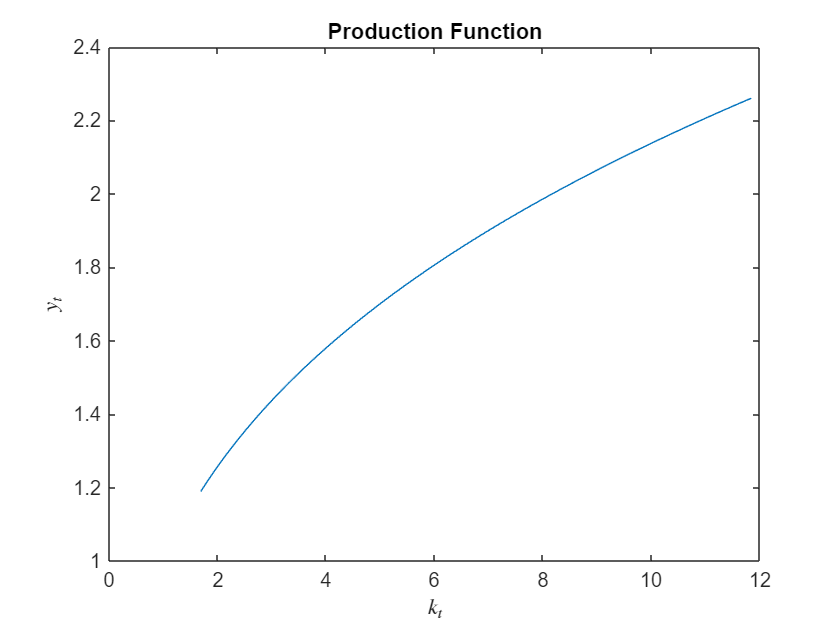

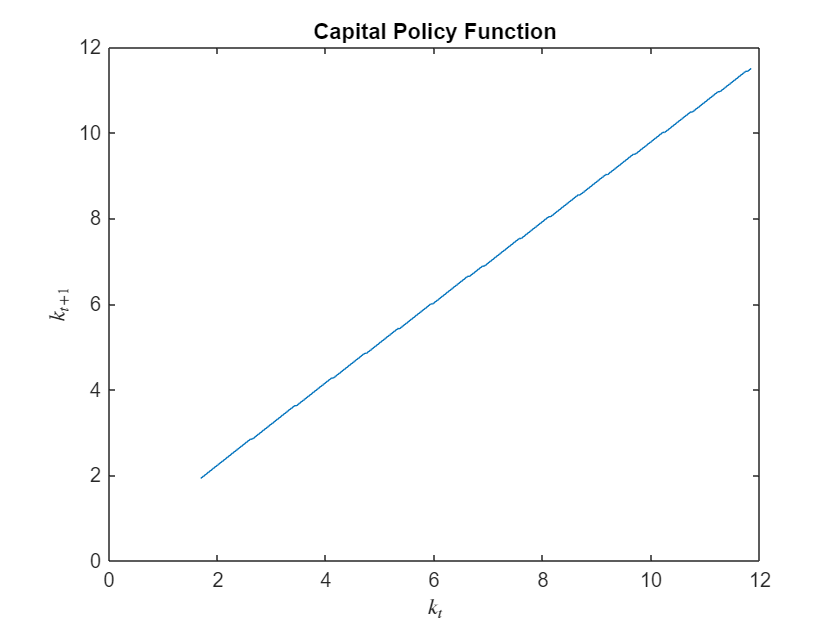

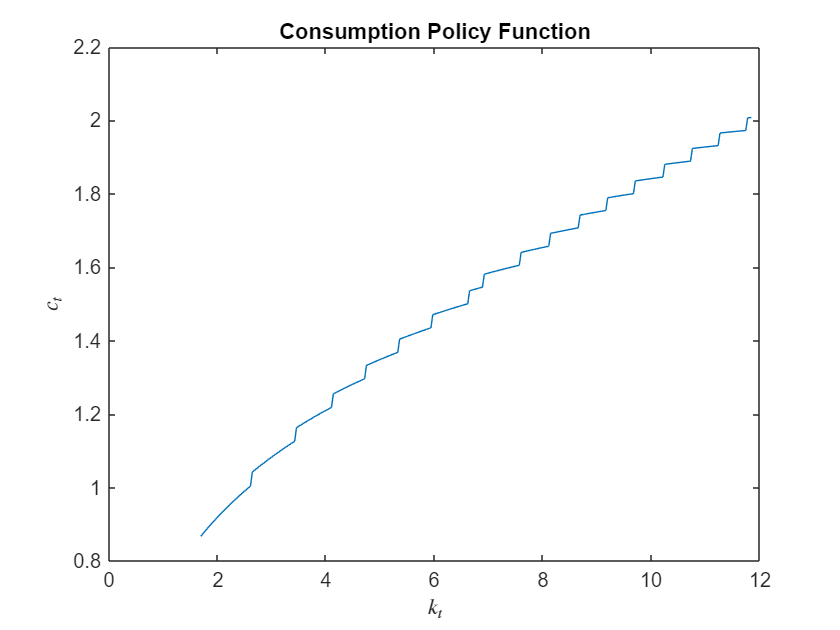

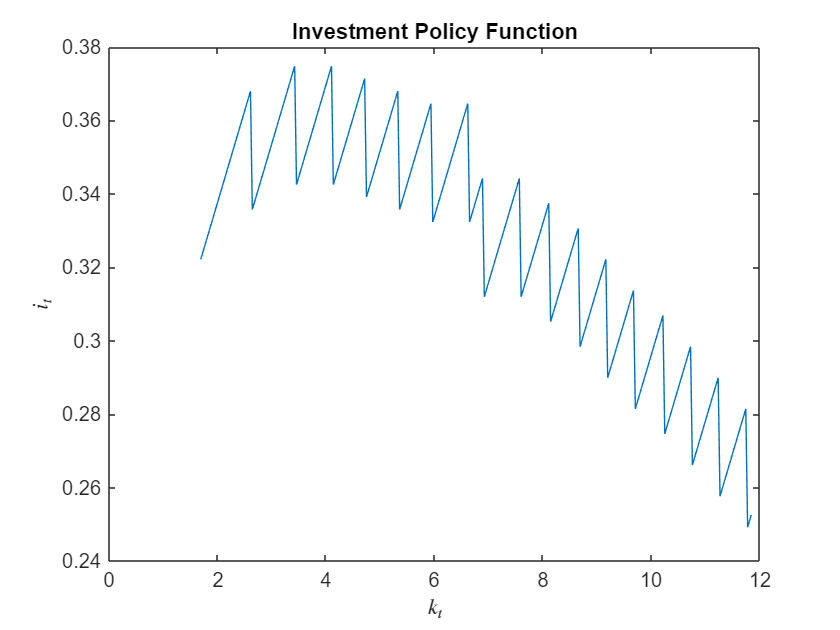

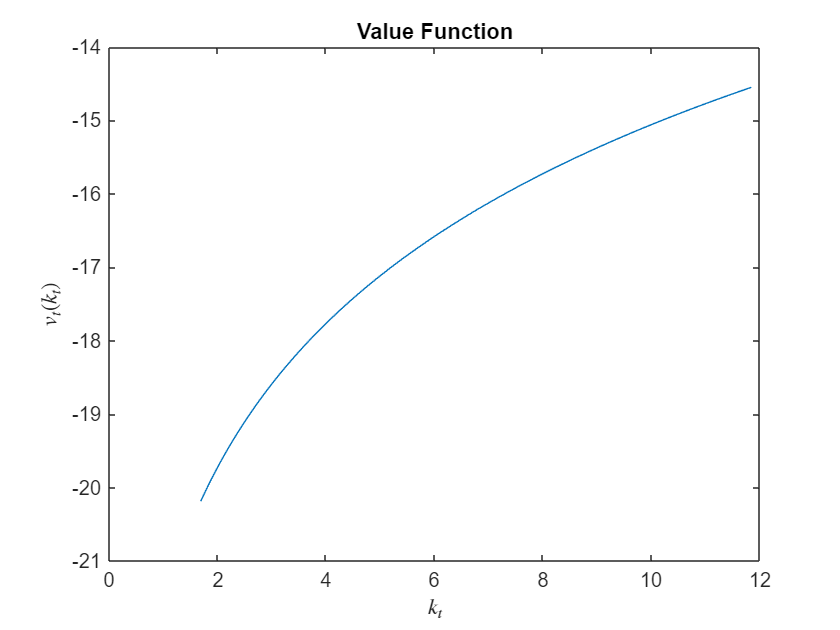

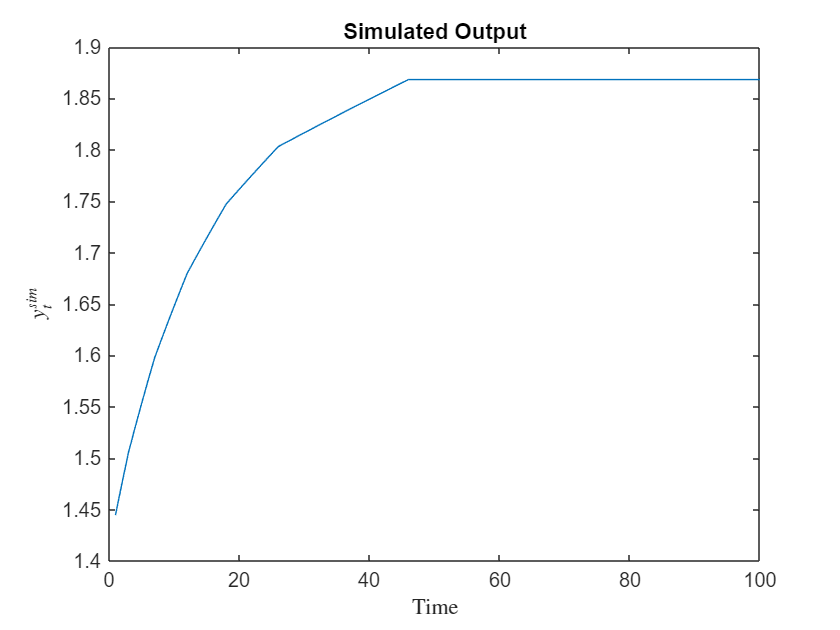

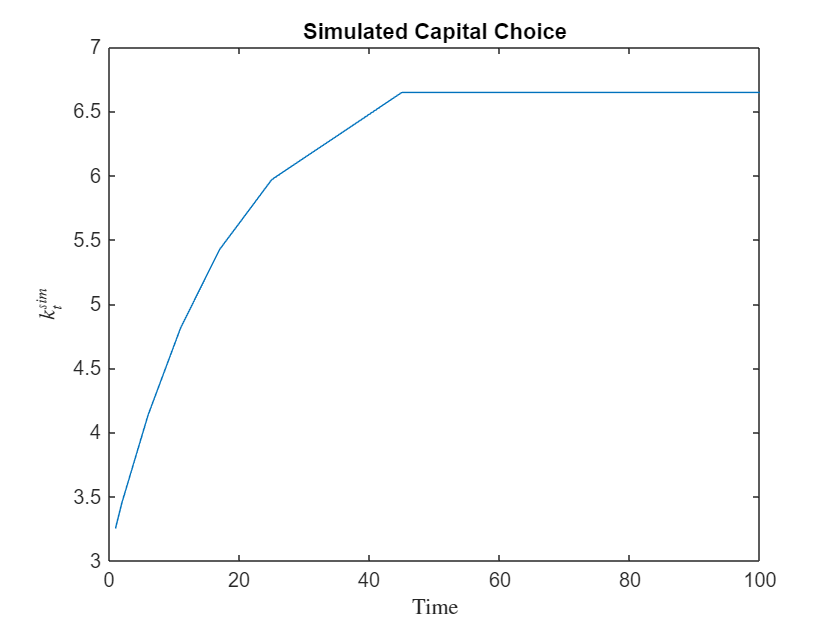

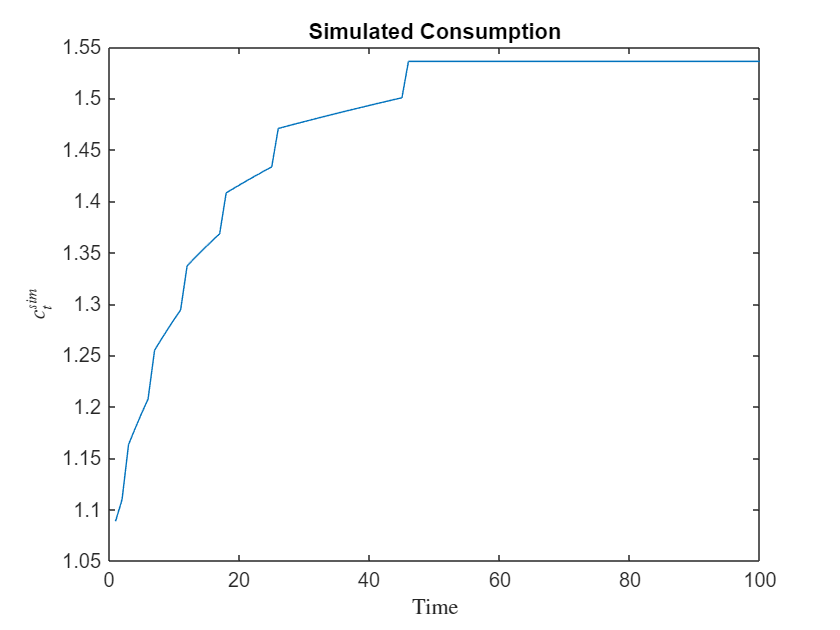

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.